# lrr demo dm

演示LRR，用于《数据挖掘》的pre。

## 人脸聚类

### 数据预处理

clear
warning off all
data_dir = '../dataset/YaleB';
addpath(genpath(data_dir));
addpath(genpath('../util'));
addpath(genpath('../performance'));
load EYaleB_2016.mat

#### 预处理1---数据归一化到[0,1]，minMax归一化

fea = fea / 255;

#### 选择簇的数量

nCluster = 10;           % number of subspace
fea = fea(:,1:num(nCluster));
gnd = gnd(:,1:num(nCluster));

#### 预处理2---PCA 降维，降维至 nCluster*6

dim = nCluster * 6;  % 降维至nCluster*6；
%% PCA Projection
[ eigvector , eigvalue ] = PCA(fea) ;
data = eigvector(:,1:dim)'*fea;
for jj = 1 : size(data,2)
   data(:,jj) = data(:,jj)/norm(data(:,jj));  % 对data的每一列（每个样本）进行归一化
end

### 运行LRR

fprintf('LRR进行人脸聚类');

LRR进行人脸聚类

fprintf('聚类簇数：%d',nCluster);

聚类簇数：10

lambda = 1;
lambda

lambda = 1


[~, Aff] = LRR(data, lambda);
% Aff = get_Aff(Z,data,aff_type,gamma);
% % 对亲和矩阵的每列进行归一化
% Aff2 = Aff;
% for i = 1 : size(Aff,2)
%    Aff2(:,i) = Aff(:,i)/(max(abs(Aff(:,i)))+eps);    
% end
[groups] = spectral_clustering(Aff,nCluster);  % 进行谱聚类
[metrics.ca, metrics.nmi, metrics.ar, ~, ~, ~] = compute_metrics(gnd, groups);
metrics

metrics = 包含以下字段的 struct :
     ca: 0.9594
    nmi: 0.9282
     ar: 0.9060


### 可视化

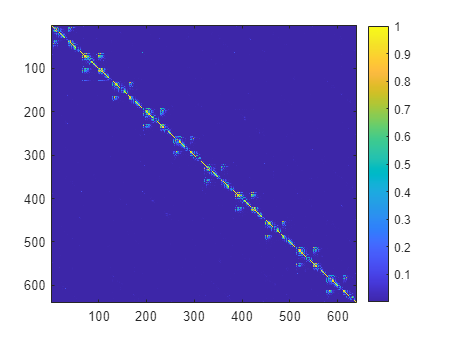

image(Aff,'CDataMapping','scaled')
colorbar